Name    : Pranay Borgohain

Roll No. : 20EE01015

# **Image and Video Processing Tutorial - 2**

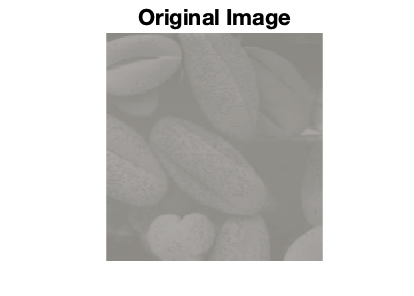

% To read test image and inputs in a matrix form
input_img  = imread('./assets/tut2-img.png');

figure;
imshow(input_img);
set(gca,'OuterPosition',[0 0 1 1])
title("Original Image");

### Image Resizing

% Check image size
disp(size(input_img));

   199   189     3



% Convert to grayscale image and resize to 300 x 300
img = rgb2gray(input_img);
img = imresize(img, [300, 300]);
disp(size(img));

   300   300



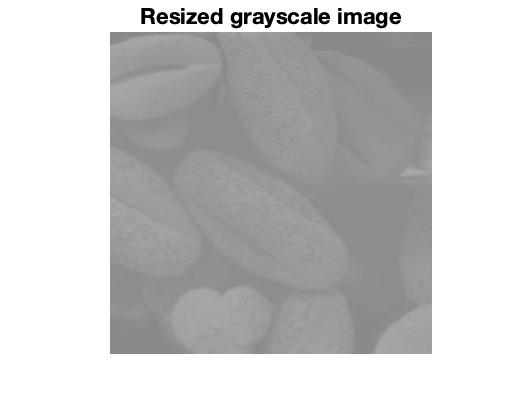

figure;
imshow(img);
set(gca,'OuterPosition',[0 0 1 1])
title("Resized grayscale image");

### Histogram Computation


$$p_r(r_k) = \frac{n_k}{MN}$$


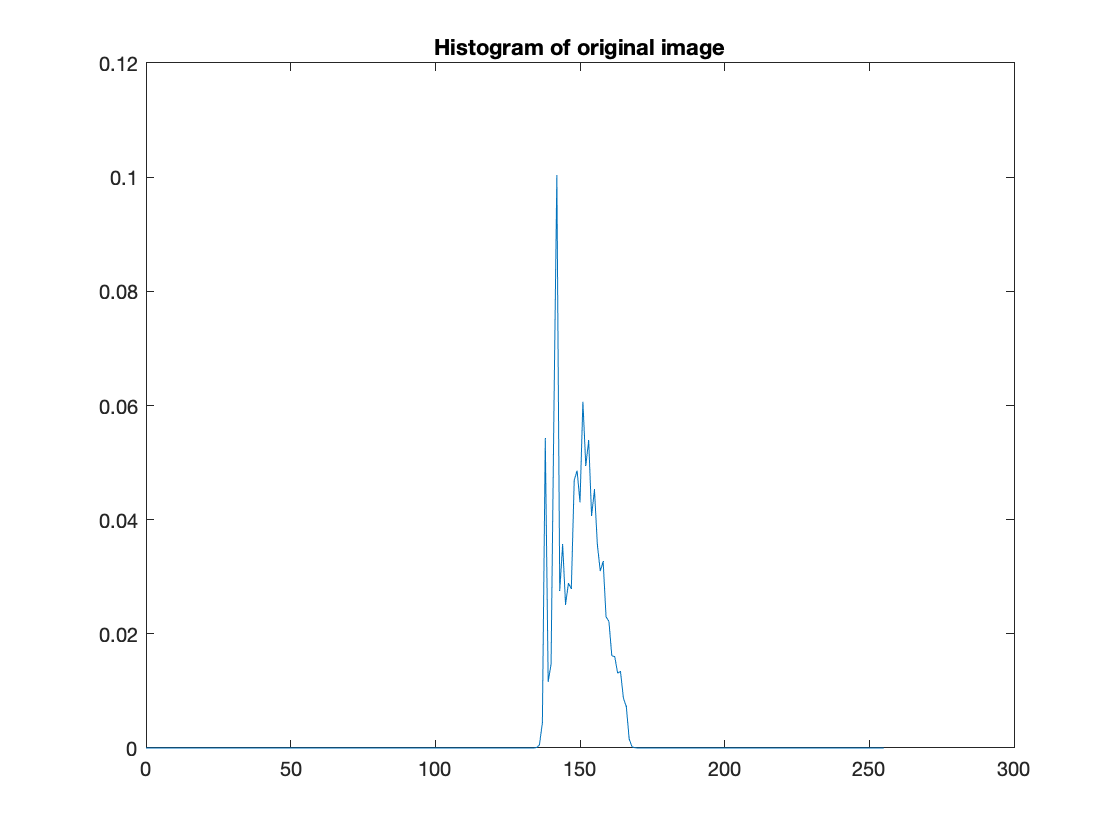

% Compute histogram of this image
p_r = zeros(1, 256);
[M, N] = size(img);

% Calculating nk, the number of pixels of each intensity value in [0, 255]
for i = 1:M
    for j = 1:N
        p_r(img(i, j) + 1) = p_r(img(i, j) + 1) + 1;
    end
end
% Normalise histogram values
p_r = p_r / (M * N);

figure;
plot(0:255, p_r);
title("Histogram of original image");

### Histogram Equalisation


$$s_k  = T(r_k) =(L-1)\cdot \sum_{i = 0}^{k}p_r(r_i)$$


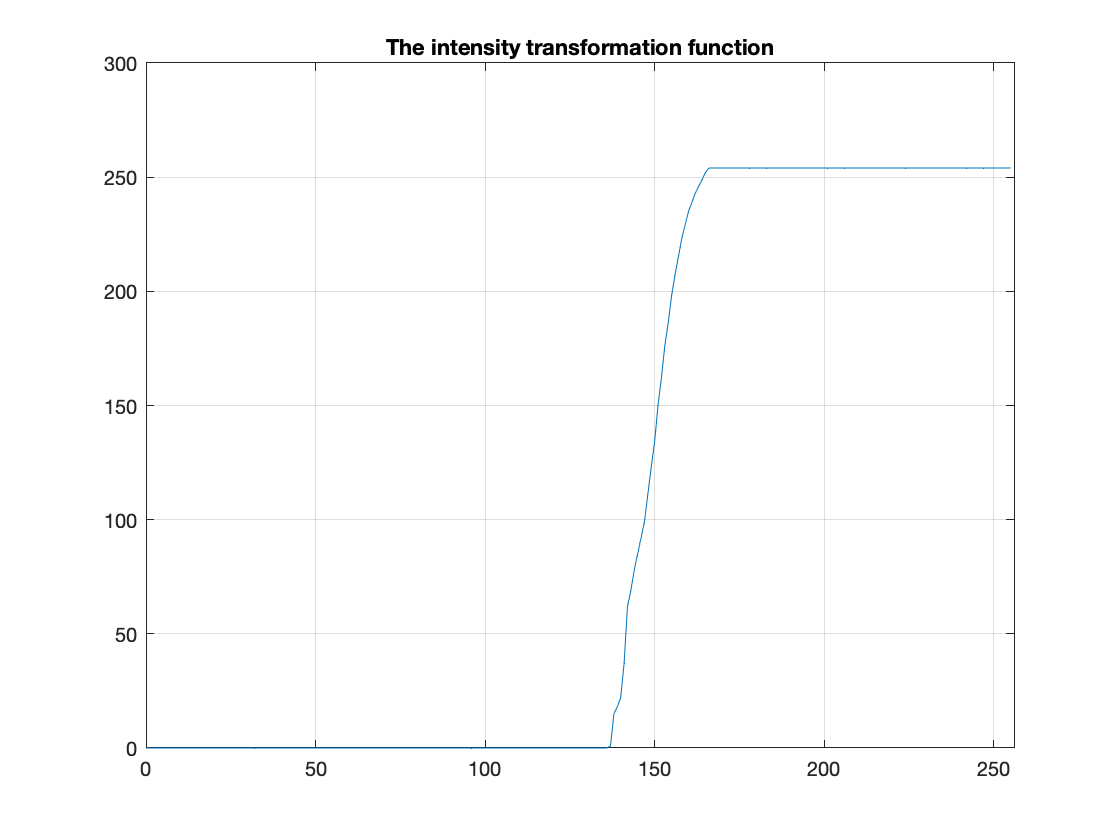

T = zeros([1, 256], 'uint8'); % Mapping from r to s
L = 255;

% Compute the intensity transformation function
for r_k = 1:256
    T(r_k) = round((L - 1) * sum(p_r(1:r_k)));
end

figure;
plot(0:255, T);
grid on; xlim([0, 256]);
title("The intensity transformation function");

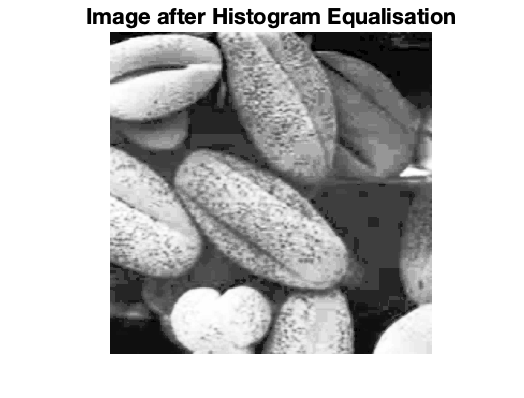

% Apply the intensity transformation function on the original image
img_equalised = zeros(size(img), 'uint8');
for i = 1:size(img, 1)
    for j = 1:size(img, 2)
        img_equalised(i, j) = T(img(i, j) + 1);
    end
end

figure;
imshow(img_equalised);
set(gca,'OuterPosition',[0 0 1 1])
title("Image after Histogram Equalisation");

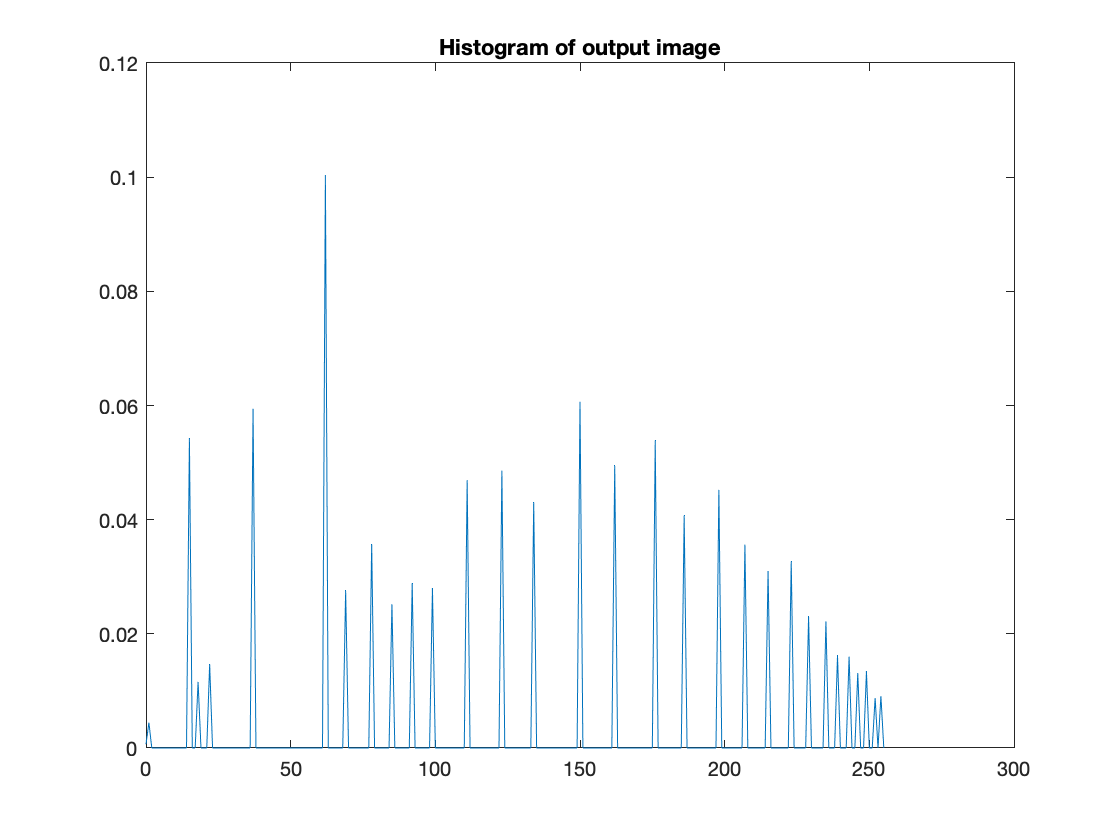

% Compute histogram of output image
p_s = zeros(1, 256);

% Calculating nk, the number of pixels of each intensity value in [0, 255]
for i = 1:M
    for j = 1:N
        p_s(img_equalised(i, j) + 1) = p_s(img_equalised(i, j) + 1) + 1;
    end
end
% Normalise histogram values
p_s = p_s / (M * N);

figure;
plot(0:255, p_s);
title("Histogram of output image");

In the discrete case, due to slight deviation introduced by using the `round()` function (so that pixel values of the output are integers in [0, 255]), the resulting histogram is not *exactly *equal to a flat line at value 1/(L-1).

### Repeated Histogram Equalisation

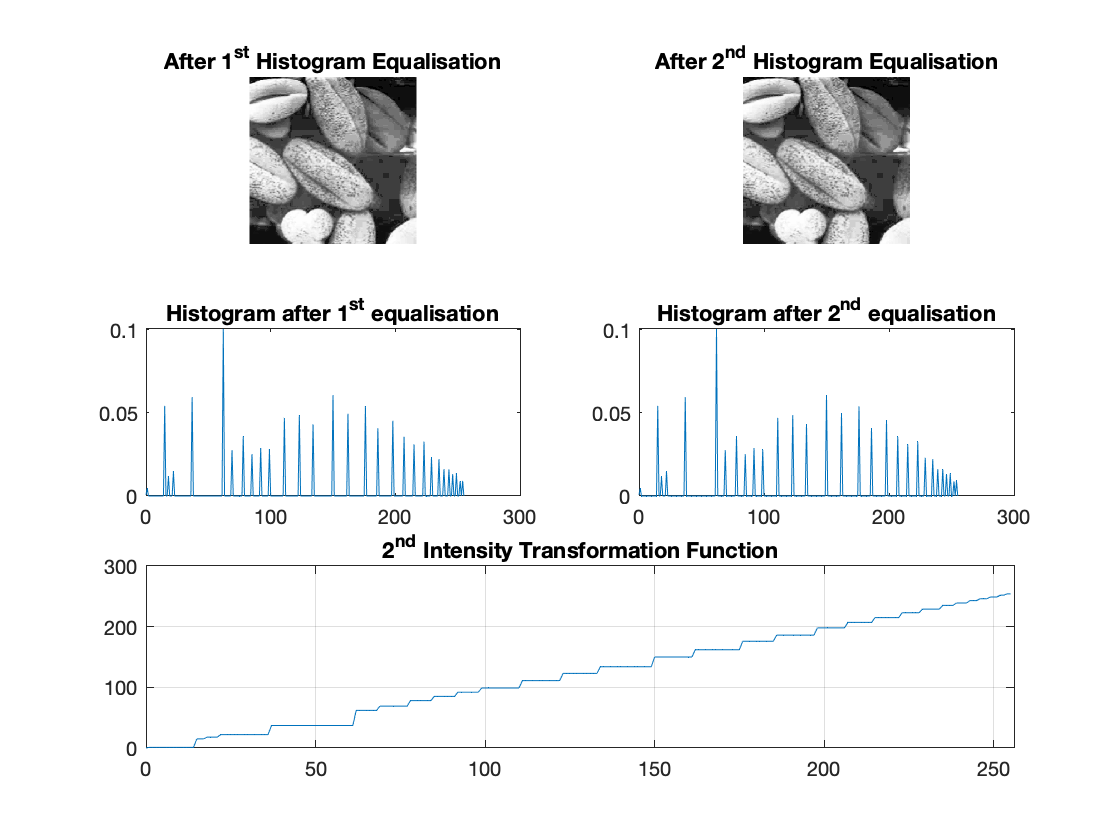

[img_equalised_again, p_s2, T2] = hist_equalisation(img_equalised);

figure;
subplot(3, 2, 1);
imshow(img_equalised);
title("After 1^{st} Histogram Equalisation");
subplot(3, 2, 2);
imshow(img_equalised_again);
title("After 2^{nd} Histogram Equalisation");
subplot(3, 2, 3);
plot(0:255, p_s);
title("Histogram after 1^{st} equalisation");
subplot(3, 2, 4);
plot(0:255, p_s2);
title("Histogram after 2^{nd} equalisation");
subplot(3, 2, [5, 6]);
plot(0:255, T2);
grid on; xlim([0, 256]);
title("2^{nd} Intensity Transformation Function");

Theoretically, repeated histogram equalisations do not have any effect, and the Intensity Transformation Function of repeated Histogram Equalisations is the identity function.


$$\Rightarrow (s_k)_2 = T_2(r_k) = (L-1) \int_0^{s_k}p_s(w)\cdot dw$$



$$\Rightarrow (s_k)_2 = T_2(r_k) = (L-1) \int_0^{s_k} \frac{1}{L-1} \cdot dw$$



$$\Rightarrow (s_k)_2 = T_2(r_k) = s_k$$


We can see that the above is approximately true even in the discrete case. The 5th sub-plot in the previous figure, titled "2nd Intensity Transformation Function" is almost equal to an identity function. The slight deviation from the identity funtion (step like shape) is due to the quantization error introduced by using the `round()` function. Hence even in the discrete case, repeated histogram equalisations don't provide any further (substantial) improvements.

### Comparision with MATLAB built-in function `histeq()`

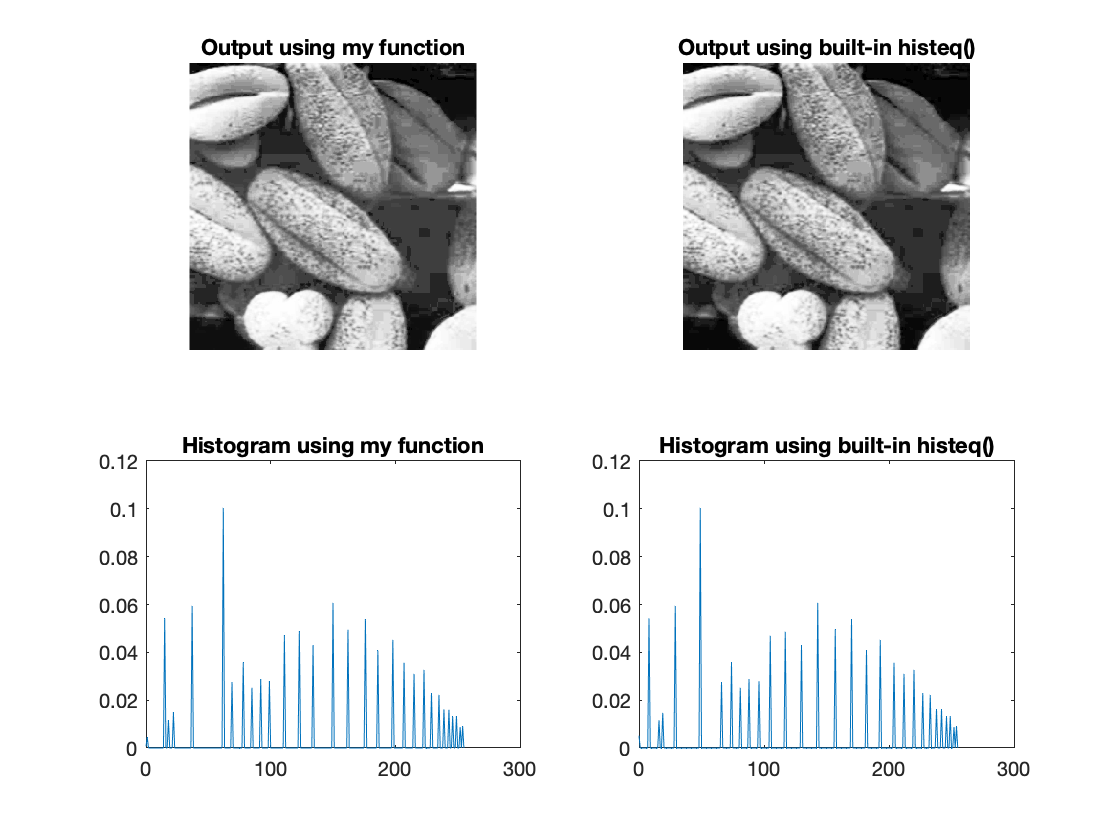

L = 255;
img_equalised_builtin = histeq(img, ones([1, 255]) * 1/(L-1));
hist_using_histeq = get_histogram(img_equalised_builtin);

figure;
subplot(2, 2, 1);
imshow(img_equalised);
title("Output using my function");
subplot(2, 2, 2);
imshow(img_equalised_builtin);
title("Output using built-in histeq()");
subplot(2, 2, 3);
plot(0:255, p_s);
title("Histogram using my function");
subplot(2, 2, 4);
plot(0:255, hist_using_histeq);
title("Histogram using built-in histeq()");

The above shows that the outputs generated by my code, and the MATLAB built-in function `histeq`() are quite similar.

function [img_out, hist_out, T] = hist_equalisation(img)
    % Compute histogram of input image
    hist_in = get_histogram(img);
    % Compute intensity transformation function
    T = zeros([1, 256], 'uint8');
    L = 255;
    for r_k = 1:256
        T(r_k) = round((L - 1) * sum(hist_in(1:r_k)));
    end
    % Perform intensity transform on input image
    img_out = zeros(size(img), 'uint8');
    for i = 1:size(img, 1)
        for j = 1:size(img, 2)
            img_out(i, j) = T(img(i, j) + 1);
        end
    end
    % Compute histogram of output image
    hist_out = get_histogram(img_out);
end

function hist = get_histogram(img)
    [M, N] = size(img);
    hist = zeros(1, 256);
    for i = 1:M
        for j = 1:N
            hist(img(i, j) + 1) = hist(img(i, j) + 1) + 1;
        end
    end
    hist = hist / (M * N);
end